# Crystal lattice image and distortion of that image

## 1    The crystal lattice

### 1.1 Creation of the lattice by defining points

The following image is a dot defined by equally-spaced Gaussian disks that are $8$ pixels in diameter. This represents accurately enough a single atom in a crystal lattice, or so it does as the author speculates.

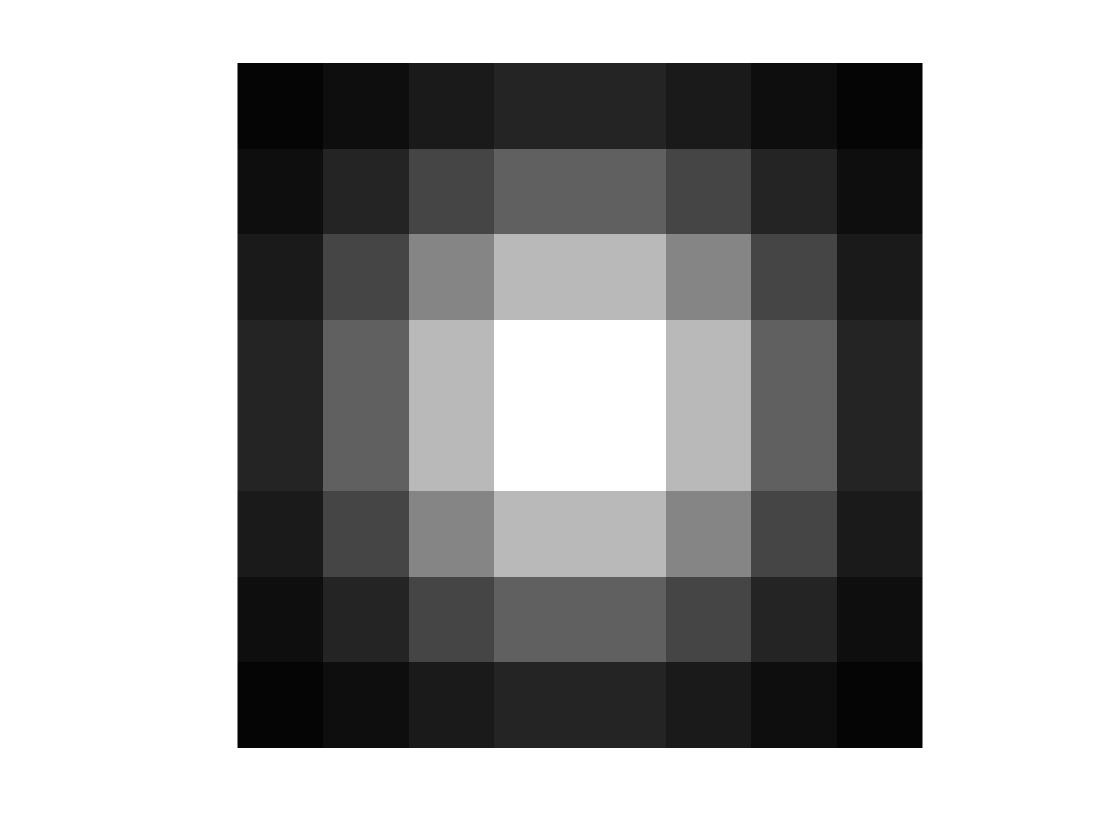

atom = fspecial("gaussian",8,1.75);
atom = atom*256/max(atom,[],"all");
I = uint8(atom);
imshow(I,"InitialMagnification","fit")

The following duplicates the "atoms" to fill a $1024\times1024$ image. To maintain consistency with latter figures, the image is also displayed using the imagesc plotting function.

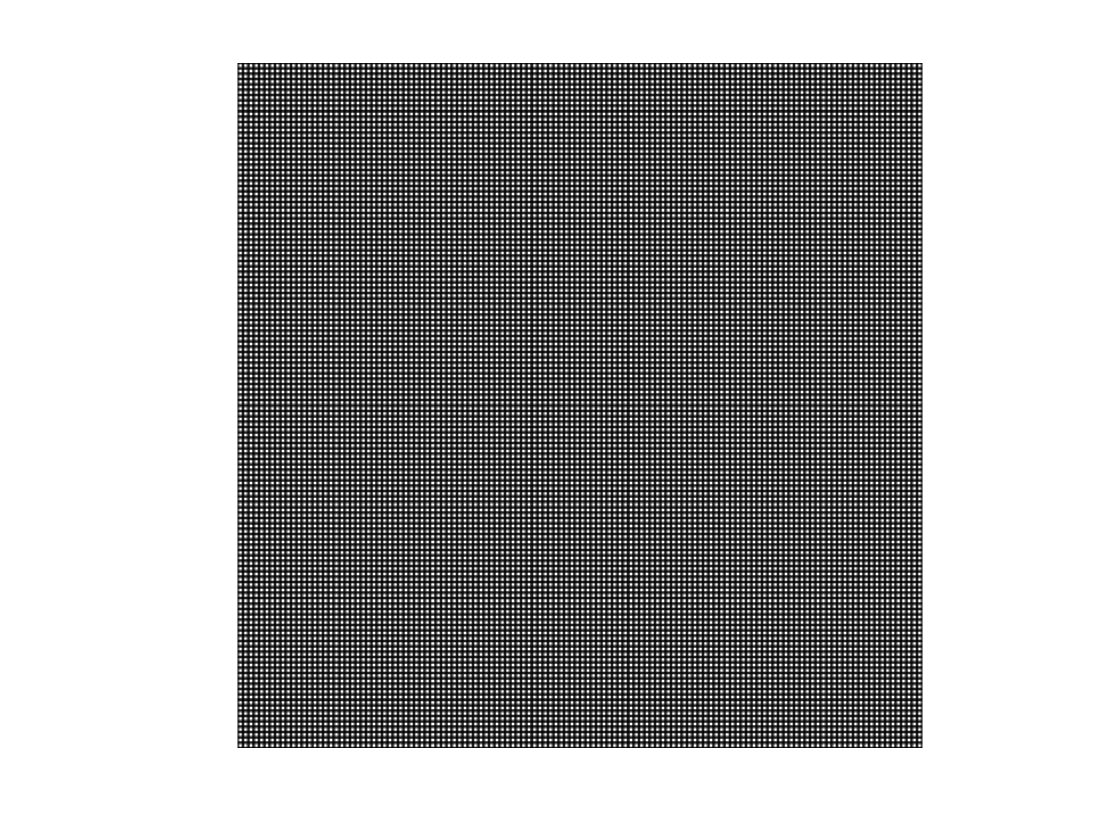

J = zeros(1024,"uint8");
for i = 1:1024
    for j = 1:1024
        J(i,j) = I(mod(i-1,8)+1,mod(j-1,8)+1);
    end
end
imshow(J,"InitialMagnification","fit")

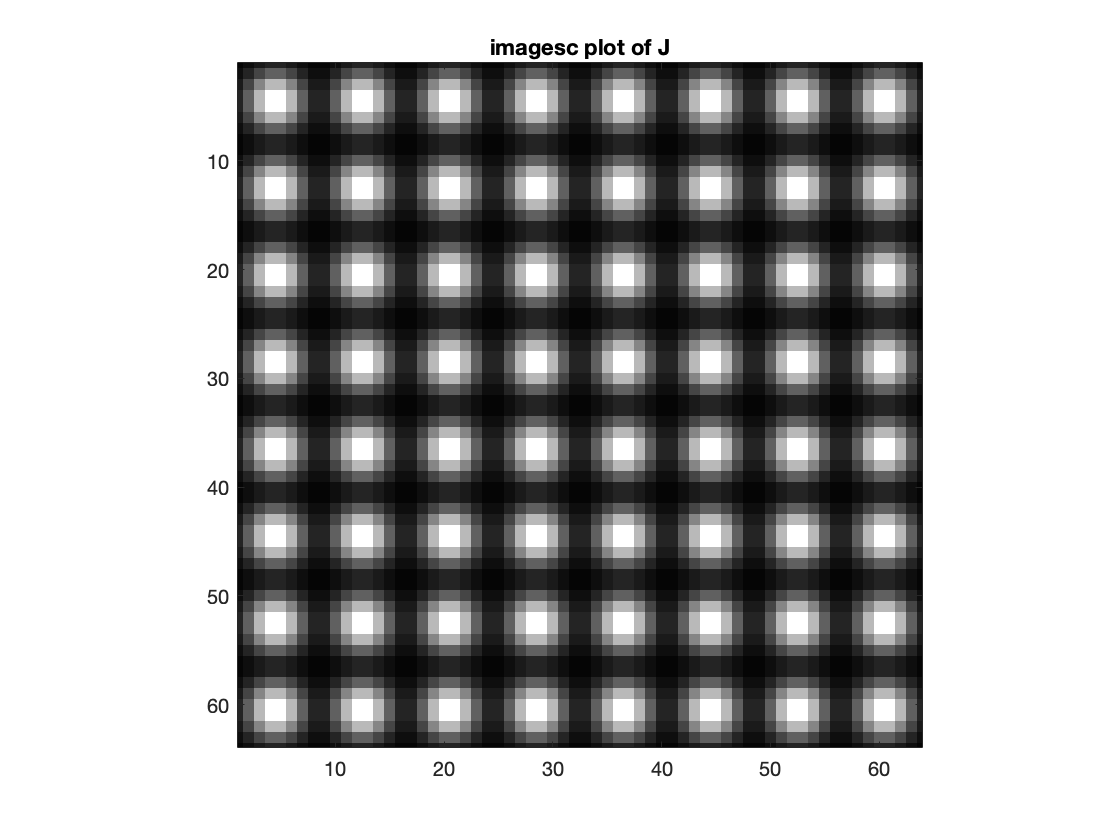


% imagesc plot like the one in section 1.3
imagesc(J, [0 255])
colormap(gray);
axis equal tight
xlim([1 64]);
ylim([1 64]);
title("imagesc plot of J")

### 1.2 Applying the Fourier transform to the defined image

The lattice is perfect, so as a consequence, the Fourier transform of the image outputs point-like singularities. Notice the plot after the Fourier Transform.

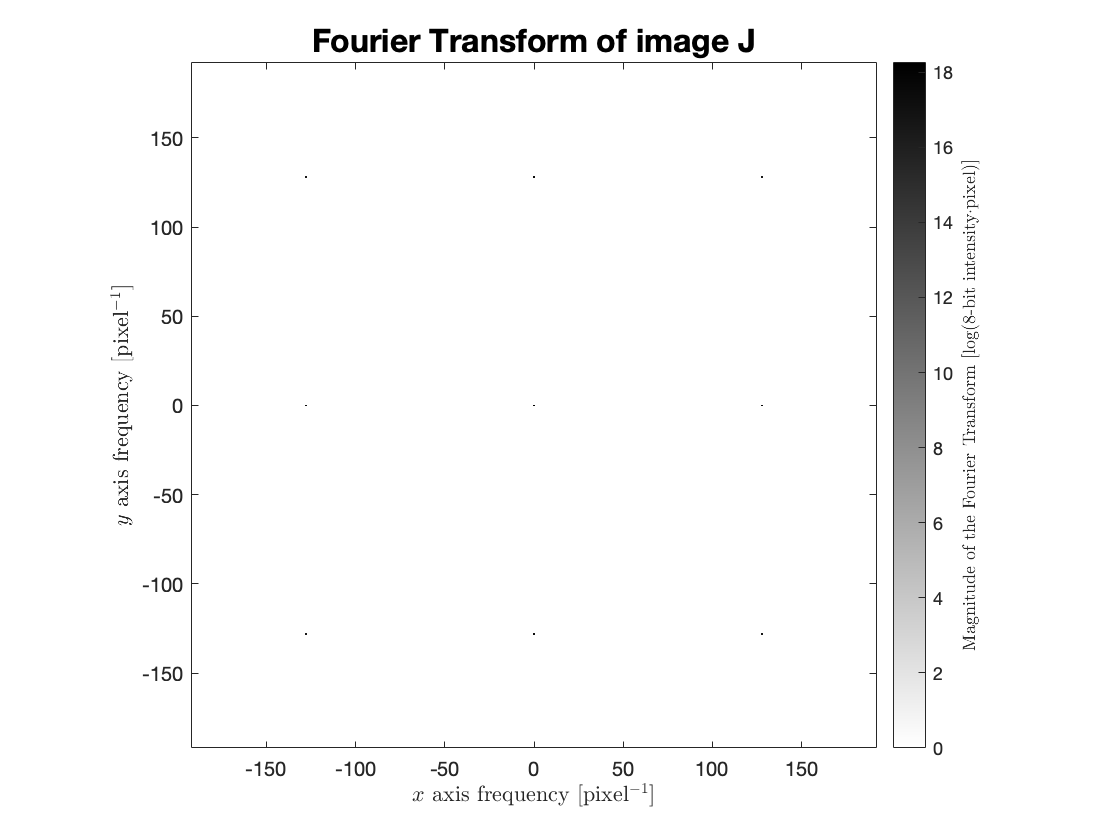

J_FT = fftshift(fft2(J));
J_FT = log(abs(J_FT));

r = 0.1;
n = 7.5;
J_FTm = J_FT(~isinf(J_FT));
ra = max(J_FTm,[],"all")-min(J_FTm,[],"all");
mu = mean(J_FTm,"all");

% clims = [mu-r*ra/2+n mu+r*ra/2+n];
% just to rescue this very special case of unusually well-ordered lattice
clims = [0,max(J_FT(~isinf(J_FT)),[],"all")];
imagesc(-512,-512,J_FT, clims);
colormap(flipud(gray));
set(gca,"YDir","normal");
axis equal
c = colorbar;

xlim([-64*3 64*3]);
ylim([-64*3 64*3]);
xlabel("$x$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
ylabel("$y$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
c.Label.String = "Magnitude of the Fourier Transform [log(8-bit intensity$\cdot$pixel)]";
c.Label.Interpreter = "Latex";
t = title("Fourier Transform of image J");
t.FontSize = 16;

### 1.3 Creating a crystal lattice by defining the 2D frequency and applying the inverse Fourier transform

This is so that we can create a crystal lattice after applying the inverse Fourier transform.

The code below is interesting only as a first attempt.

% useless remnant code
% FT = [0 1 0; 1 1 1; 0 1 0];
% iFT = abs(ifft2(FT))

The code below is a test to check the amount of information retained after applying the Fourier transform and the inverse Fourier transform to an image. 

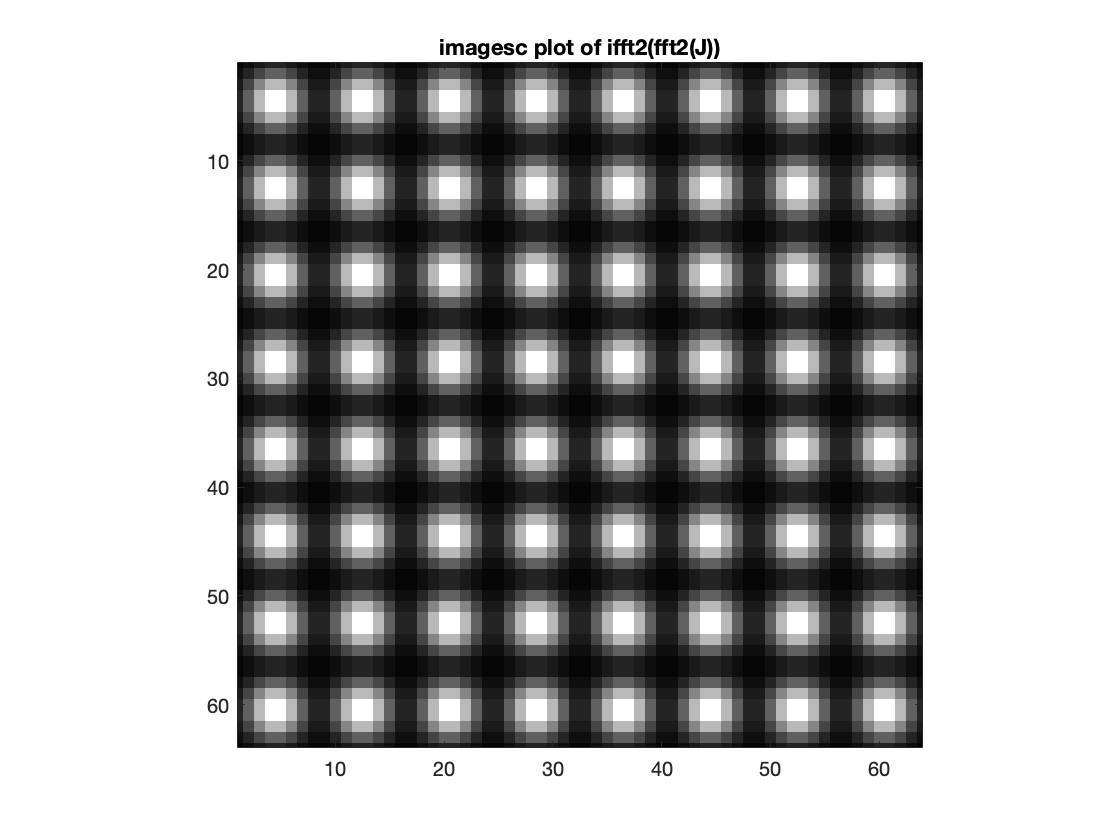

% insightful piece of code

iFTj = ifft2(fft2(J));
% imshow(uint8(iFT),"InitialMagnification","fit")
% imshow(J-uint8(iFT))
imagesc(iFTj, [0 255])
colormap(gray);
axis equal tight
xlim([1 64]);
ylim([1 64]);
title("imagesc plot of ifft2(fft2(J))")

Taking the absolute value of the Fourier transform and then applying the the inverse Fourier transform results to an interesting image. The "atoms" are shifted a radius parallel to each direction. The center-center distance is maintained at $8$ pixels.

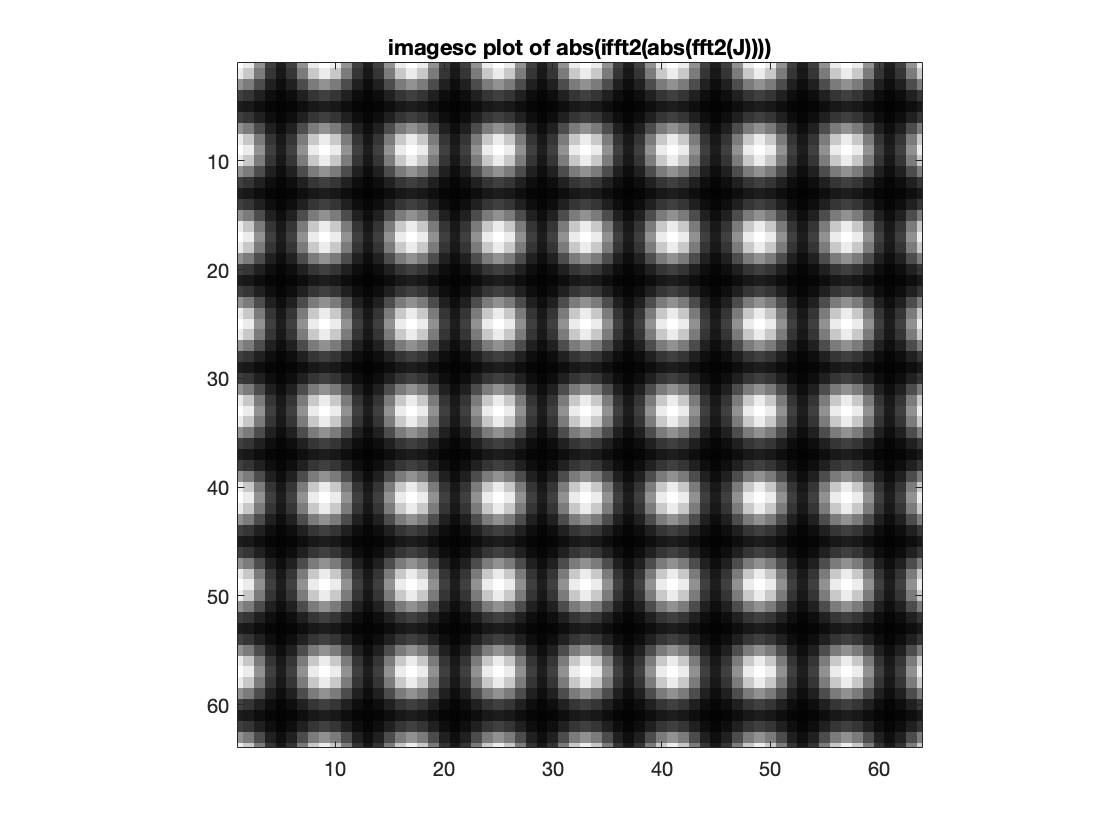

iFTj = abs(ifft2(abs(fft2(J))));
imagesc(iFTj, [0 255])
colormap(gray);
axis equal tight
xlim([1 64]);
ylim([1 64]);
title("imagesc plot of abs(ifft2(abs(fft2(J))))")

*I realized that it is challenging to build a crystal lattice by applying the inverse Fourier transform to a matrix with values obtained from scratch. While I believe it is technically possible, it is difficult to specify the "atoms"'s radii and overall shape.*

In any case, let me try.

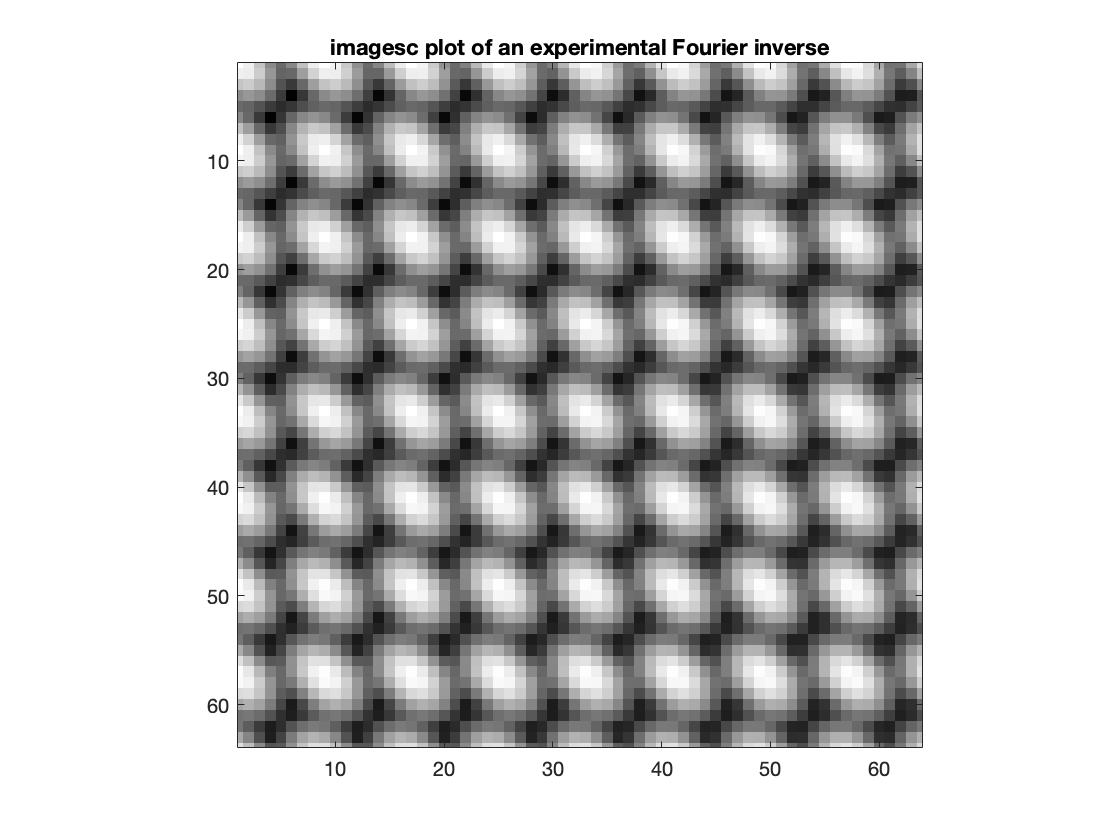

FT = zeros(1024);
FT(128,1) = 2.5e8;
FT(1,128) = 2.5e8;
FT(128,128) = 2.5e8*sqrt(2);
% FT(1024,1) = 2.5e8;
% FT(1024,128) = 2.5e8;
% FT(1024-128,128) = 2.5e8;
iFT = abs(ifft2(FT));

imagesc(iFT) % note that I removed the [0 255] colorbar limits
% imagesc(iFT, [0 255])
colormap(gray);
axis equal tight
xlim([1 64]);
ylim([1 64]);
title("imagesc plot of an experimental Fourier inverse")

Okay, so we got weird ribbons (try the [0 255] limits). Without the [0 255] limits, they look like distorted circles. The result is not too surprising but is far from what we initially want.

disp("-------******Major section break.******-------")

-------******Major section break.******-------


clear

## 2    The transformation due to a vector field ***u***

I'll just try things out in code for now. I'll write detailed explanations later.

*later = now*

The juice of the code is no longer in the following sections but in the last section, "Functions". Basically, what I did here are:

(1) redo the things done in the first part only this time using functions. 

(2) create a vector field ***u*** that will be used to distort the perfect square lattice

(3) apply the transformation and do the Fourier transform

(4) apply the transformation in reverse and do the Fourier transform

In the end, there are some unexpected results, perhaps because I misinterpreted Fujita et al. (2010)'s equation 5 (supplemental material) or because the datatype uint8 introduces some funny round-off errors especially at 0 and 255.

### 2.1 Redo the previous part with functions

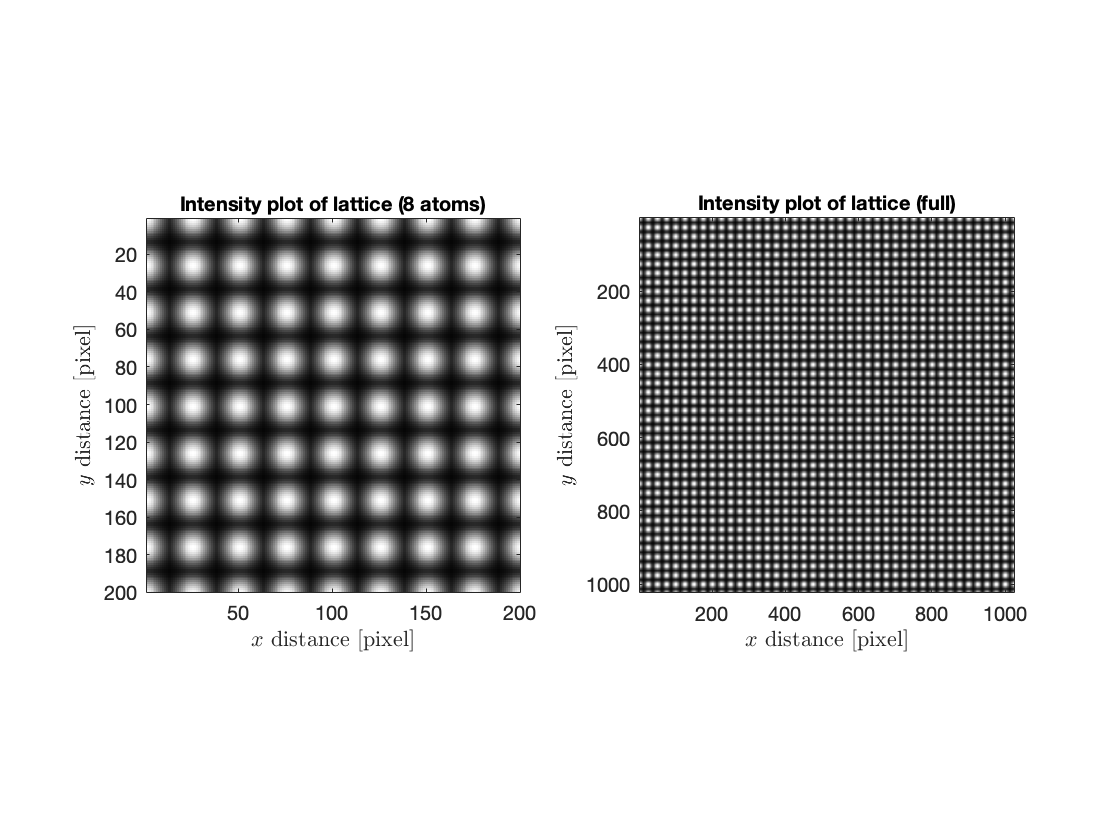

% I made a function that does the same thing as that of 1.1
image_length = 1024;
image_height = 1024;
atom_radius = 25;

lattice = createLattice(image_height,image_length,atom_radius,0.25);
comboPlot(lattice, "lattice",atom_radius);

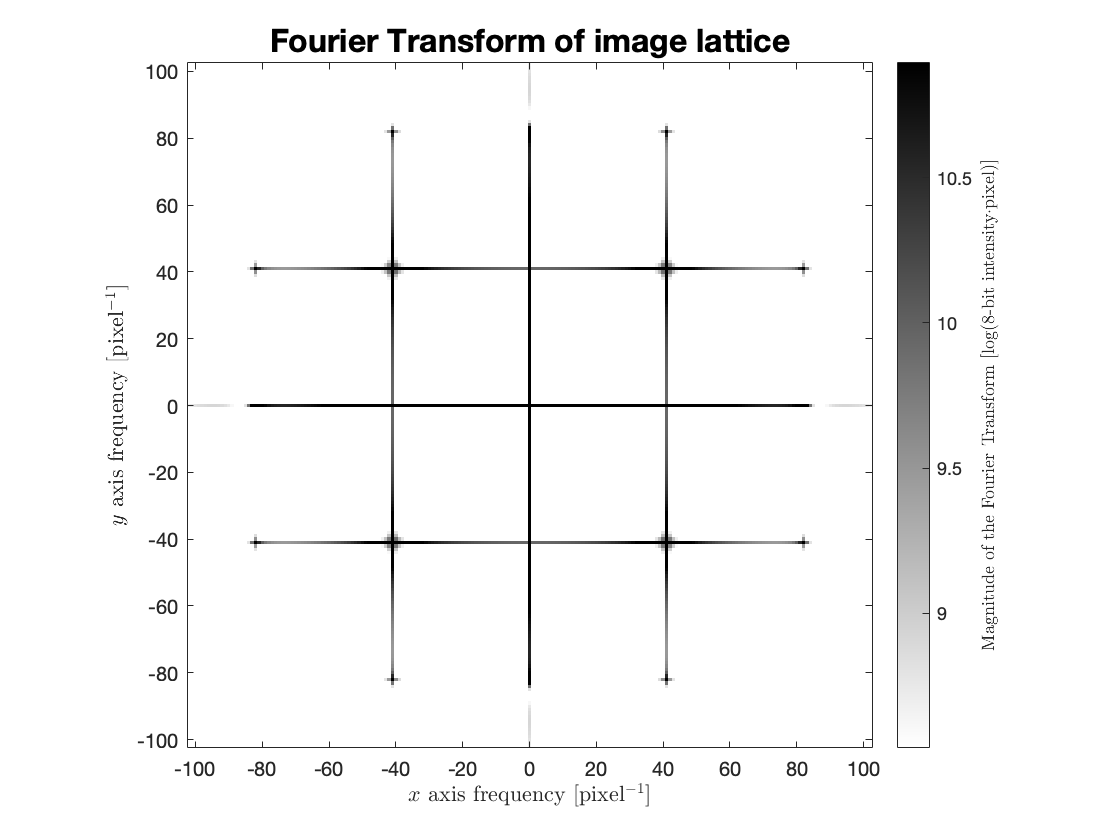


% and this one is the same as that of 1.2 with some improvements
[latticefft, Qx, Qy] = myFFT(lattice, "lattice");

### 2.2 Define *u* and plot and apply FT on *u=0*

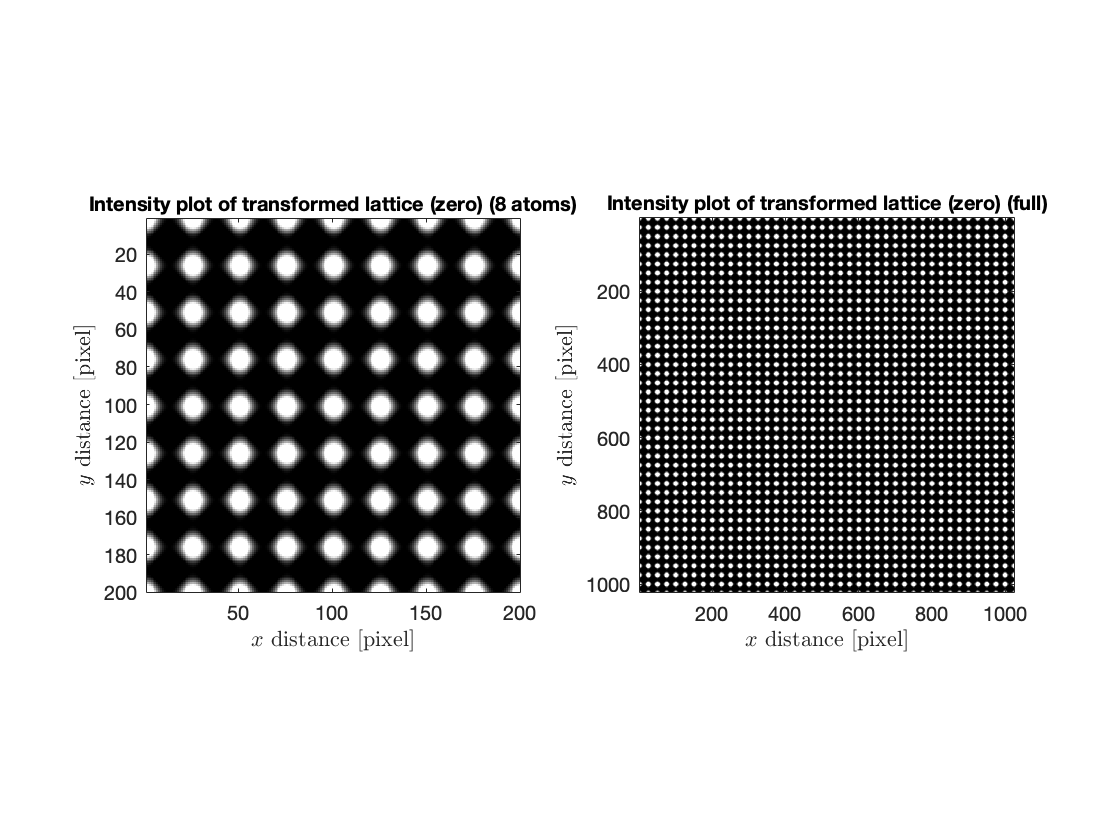

u = zeros(image_height, image_length, 2);
% u = randi(5,image_height,image_length,2)-1;


Qx = [Qx; 0]*2*pi/image_length;
Qy = [0; Qy]*2*pi/image_height;

% notice the negated u(r). r-u(r) is defined as the square lattice
latticetransform = uTransform(lattice,-u,Qx,Qy);
comboPlot(latticetransform,"transformed lattice (zero)",atom_radius);

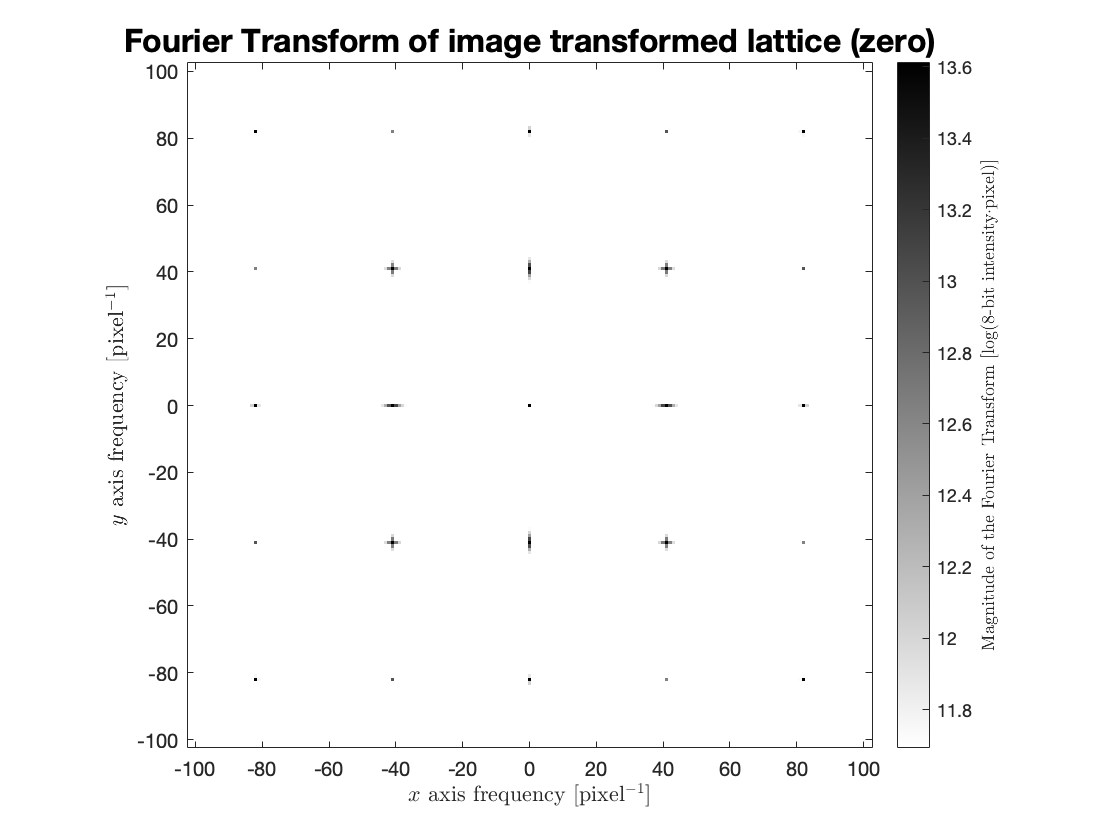


% latticePlot(lattice-latticetransform,"difference",atom_radius,8);

myFFT(latticetransform,"transformed lattice (zero)");

### 2.3 Define a more sophisticated *u* and plot and apply FT

Trying out a different *u*.

clear u
u = zeros(image_height,image_length,2);

The vector field associated with it.

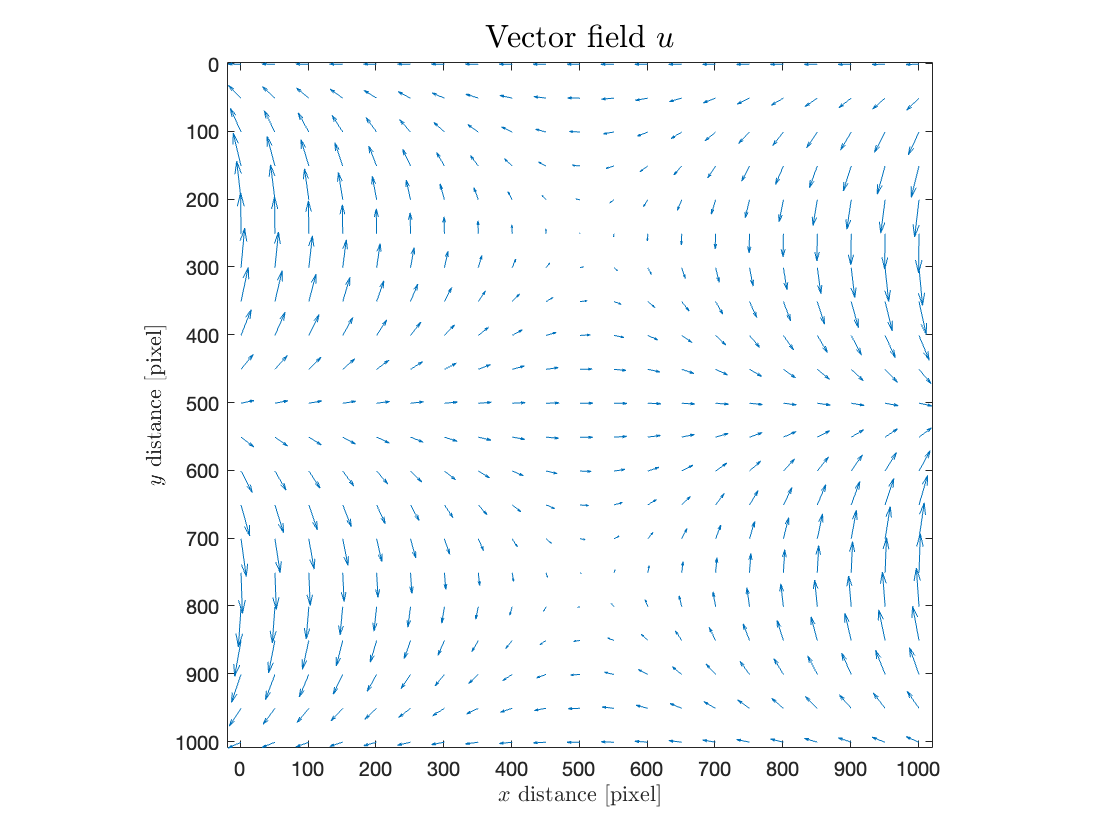

scale_coor = 1; % to scale the coordinates of the vector field
scale_mag = 15; % to scale the magnitude of the vectors in the vector field
[v,w] = meshgrid(1:image_length,1:image_height);
x = scale_coor.*(v-image_length/2)./image_length.*2.*pi;
y = scale_coor.*(w-image_height/2)./image_height.*2.*pi;
for k = 1:image_height
    for l = 1:image_length
        u(k,l,1) = cos((y(k,l)))*scale_mag;
        u(k,l,2) = -x(k,l)*sin(y(k,l))*scale_mag;
    end
end

skipx = 50*image_length/1024;
skipy = 50*image_height/1024;
x = x(1:skipx:end,1:skipy:end);
y = y(1:skipx:end,1:skipy:end);

quiver(v(1:skipx:end,1:skipy:end).*scale_coor,w(1:skipx:end,1:skipy:end).*scale_coor, ...
    cos(y),-x.*sin(y));
t = title("Vector field $u$","Interpreter","latex");
xlabel("$x$ distance [pixel]","Interpreter","latex");
ylabel("$y$ distance [pixel]","Interpreter","latex");
set(gca,"YDir","reverse");
axis equal tight;
t.FontSize = 16;

Applying *u*.

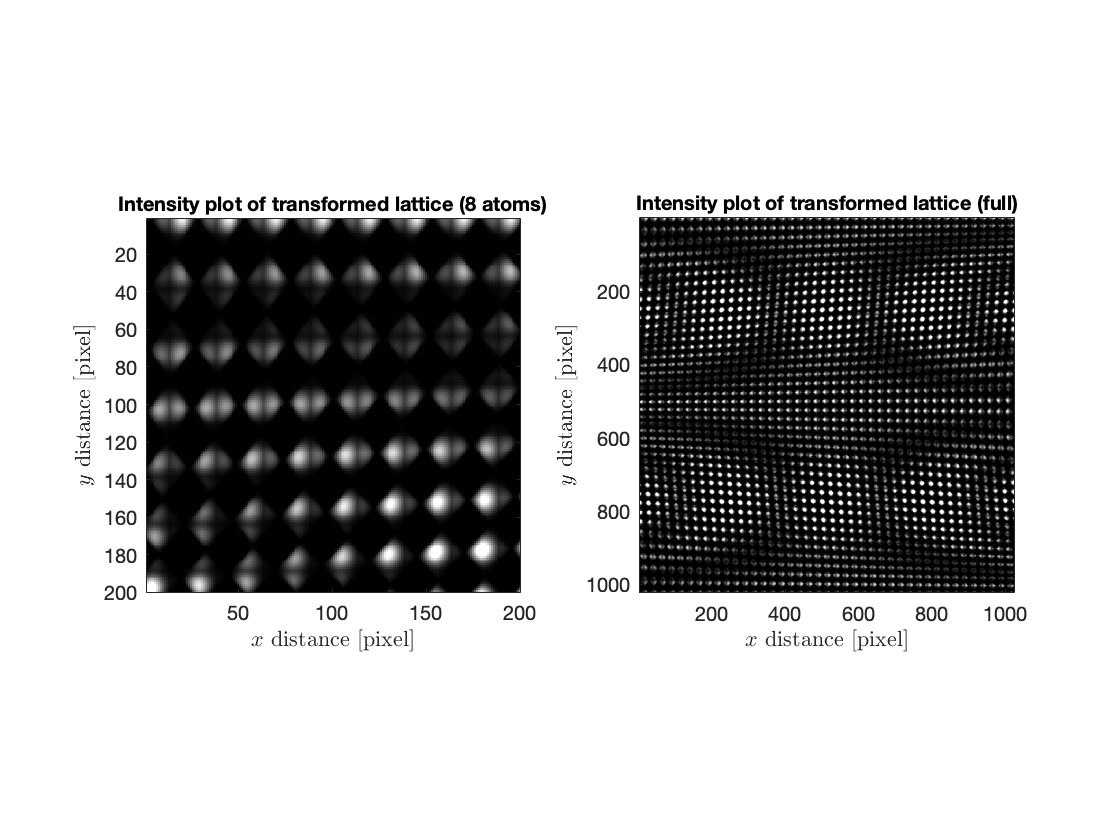

latticetransform2 = uTransform(lattice,-u,Qx,Qy);
comboPlot(latticetransform2,"transformed lattice",atom_radius);

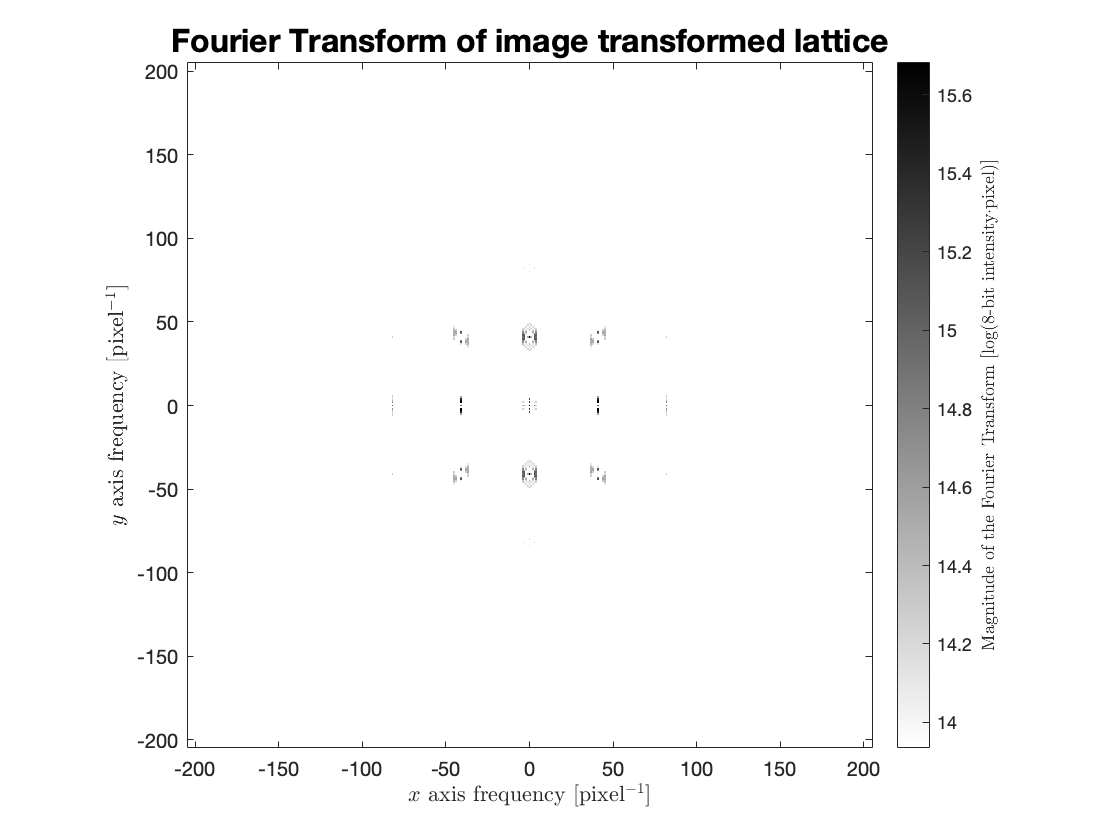


% latticePlot(latticetransform2-latticetransform,"transform difference");

lattice2fft = myFFT(latticetransform2,"transformed lattice");

### 2.4 Apply the reverse of *u* on the transformed lattice and plot and apply FT

Applying *u* in reverse.

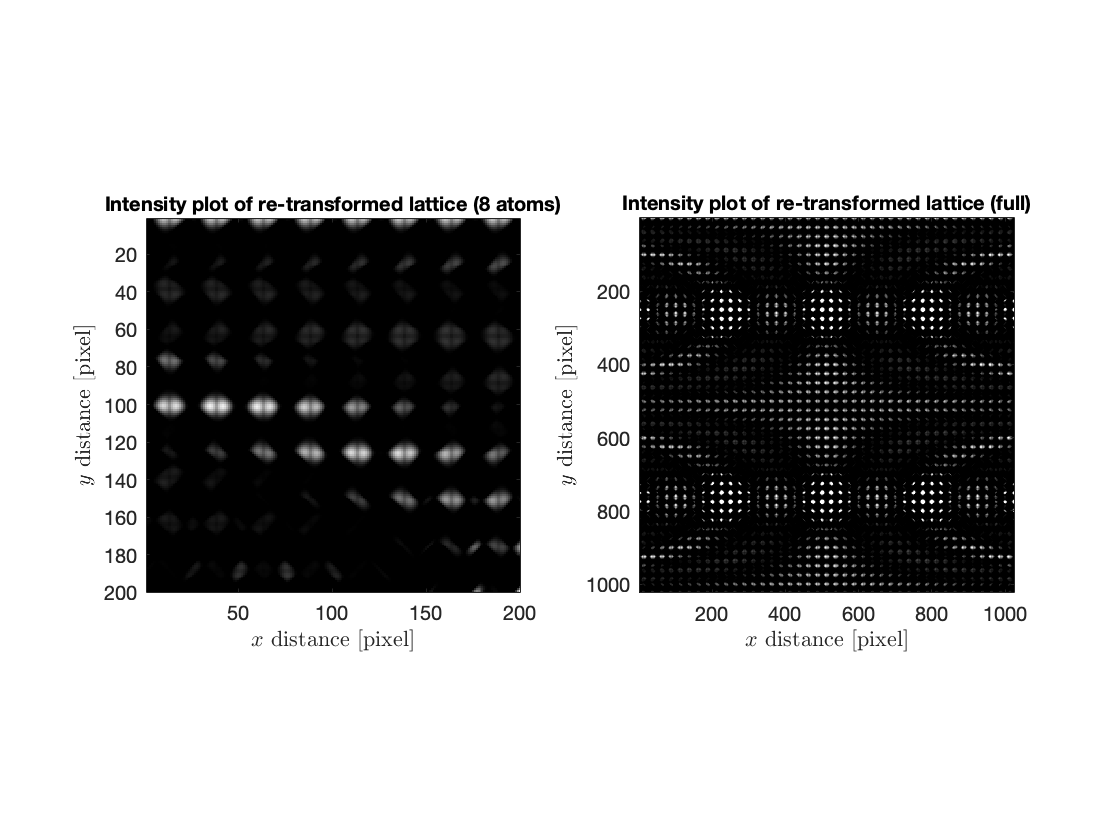

latticetransform3 = uTransform(latticetransform2,u,Qx,Qy);
comboPlot(latticetransform3,"re-transformed lattice",atom_radius);

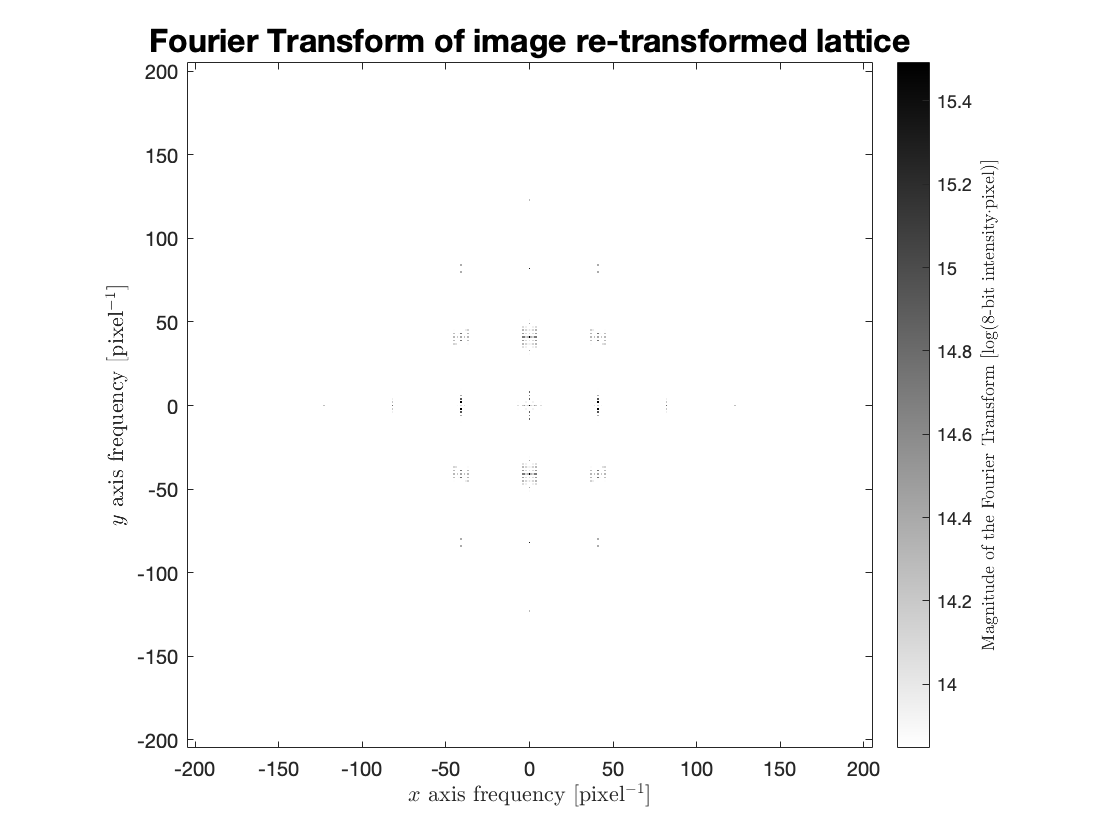


lattice3fft = myFFT(latticetransform3,"re-transformed lattice");

Overall, this exercise gave me a lot of practice, and that's great!

BUT!

The transformations according to Fujita et al. (2010)'s equation 5 still don't properly transform the lattice, or at least, not with the values that I tried with on this script (maximum displacement is 3/5 the diameter of an "atom"). I will try writing the functions with double inputs and outputs instead of uint8.

## Functions

...because I have to put them all here at the end. MatLab is quirky.

function P = createLattice(l, h, r, rel_std)
    % l, h are dimensions; r, rel_std specify the atom radius and spacing
    % nm is the title

    % create the atom just like in 1.1
    atom = fspecial("gaussian",r,rel_std*r);
    atom = uint8(atom*256/max(atom,[],"all"));
    
    % create the lattice
    P = zeros(l, h, "uint8");
    for i = 1:l
        for j = 1:h
            P(i,j) = atom(mod(i-1+floor(r/2),r)+1,mod(j-1+floor(r/2),r)+1);
        end
    end
    
    % plot the result with imagesc
%     latticePlot(P,nm,r,8);
end

function [] = latticePlot(P0,nm1,r,num)
    % P0 is the image (uint8); nm1 is the title; r, num specify the view
    
    imagesc(P0, [0 255]); % change the limits if you want
                          % to plot double or logical values
    colormap(gray);
    axis equal tight
    if nargin<4
        num = 8;
        if nargin>2
            xlim([1 r*num]);
            ylim([1 r*num]);
        end
    else
        xlim([1 r*num]);
        ylim([1 r*num]);
    end
    
    xlabel("$x$ distance [pixel]","Interpreter","latex");
    ylabel("$y$ distance [pixel]","Interpreter","latex");
    t = title("Intensity plot of " + nm1);
    t.FontSize = 10;
end

function [] = comboPlot(P0, nm, a)
    figure;
    subplot(1,2,1);
    latticePlot(P0,nm + " (8 atoms)",a,8);
    subplot(1,2,2);
    latticePlot(P0,nm + " (full)");
    figure;
end

function [Q, idx, idy] = myFFT(P, nm, r, n, noisy)
    % P is the image; r, n, noisy specify the colorbar range
    % Q is the fft; idx, idy are the indices of Qx, Qy
    
    sp = size(P);
    Q = fft2(P);
    Q1 = log(abs(Q));
    Q2 = Q1;
    Q2(isinf(Q2)) = nan;
    [~,idx] = max(Q2(2:end,1),[],"omitnan");
    [~,idy] = max(Q2(1,2:end),[],"omitnan");
%     idx = idx + 1;  % to make up for the omitted first index
%     idy = idy + 1;
    
    Q1 = fftshift(Q1);
    
    if nargin<5
        noisy = true;
        if nargin<3
            r = 0.1;
            n = 7.5;
        end
    end
    
    Q1m = Q1(~isinf(Q1));
    ra = max(Q1m,[],"all")-min(Q1m,[],"all");
    mu = mean(Q1m,"all");
    
    clims = [mu-r*ra/2+n mu+r*ra/2+n];
    if ~noisy
        clims = [0,max(Q1(~isinf(Q1)),[],"all")];
    end
    imagesc(-sp(1)/2,-sp(2)/2,Q1, clims);
    colormap(flipud(gray));
    set(gca,"YDir","normal");
    axis equal tight
    c = colorbar;
    
    xyl = max(idx,idy);
    xlim([-xyl*2.5 xyl*2.5]); % comment these to view whole Fourier transform
    ylim([-xyl*2.5 xyl*2.5]);
    xlabel("$x$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
    ylabel("$y$ axis frequency [pixel$^{-1}$]","Interpreter","latex");
    c.Label.String = "Magnitude of the Fourier Transform [log(8-bit intensity$\cdot$pixel)]";
    c.Label.Interpreter = "Latex";
    t = title("Fourier Transform of image " + nm);
    t.FontSize = 16;
end

function P2 = uTransform(P1, u1, qx1, qy1)
    % P1 is the image; u1 is the displacement vector field
    % qx1, qx2 are the modulation wavevectors
    sp = size(P1);
    P2 = zeros(sp(1),sp(2), "double");
    for i = 1:sp(2)
        for j = 1:sp(1)
            % notice the flipped coordinates to accomodate for row:y;column:x
            P2(j,i) = double(P1(j,i))*(cos(qx1'*([i-1;j-1]-[u1(j,i,1); u1(j,i,2)])) ...
                +cos(qy1'*([i-1;j-1]-[u1(j,i,1); u1(j,i,2)])));
        end
    end
    P2 = uint8(P2);
end